clear; clear path; clc;
cd('~/git/hardDiskControl/continuousTimeControl/distReject/')
load('../../data/plantTF.mat');
addpath ../../funcs/;
format shortG


[A,B,C,D]=tf2ss([200 10^6],[1 200 10^6 0 0])

A =         -200    -1000000           0           0
           1           0           0           0
           0           1           0           0
           0           0           1           0


B =      1
     0
     0
     0


C =            0           0         200     1000000


D =      0


sys = ss(A,B,C,D);
riseTime = 0.052333; %seconds
dsys = c2d(sys,riseTime/10)

dsys =
 
  A = 
               x1          x2          x3          x4
   x1      0.3337       524.1           0           0
   x2  -0.0005241      0.2289           0           0
   x3   7.711e-07  -0.0003699           1           0
   x4   5.603e-09   1.892e-06    0.005233           1
 
  B = 
               u1
   x1  -0.0005241
   x2   7.711e-07
   x3   5.603e-09
   x4    1.18e-11
 
  C = 
          x1     x2     x3     x4
   y1      0      0    200  1e+06
 
  D = 
       u1
   y1   0
 
Sample time: 0.0052333 seconds
Discrete-time state-space model.


Gz = tf(dsys)

Gz =
 
  1.292e-05 z^3 + 7.514e-06 z^2 - 3.633e-06 z + 4.791e-06
  -------------------------------------------------------
      z^4 - 2.563 z^3 + 2.476 z^2 - 1.265 z + 0.3511
 
Sample time: 0.0052333 seconds
Discrete-time transfer function.
Model Properties


P = 10;
I = 0;
D = 50;
N = 150;
Cs = pidGen(P,I,D,N,1);
Cz = c2d(Cs,riseTime/10);

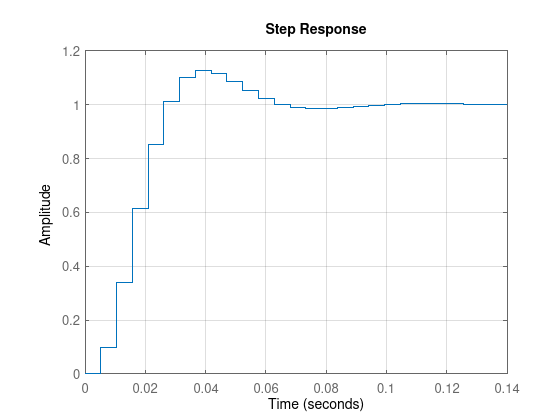

figure(1);clf; hold on;
step(Gz*Cz/(1+Gz*Cz)); grid on;

riseTime = 0.022295;
dsys = c2d(sys,riseTime/10);
Gz = tf(dsys);

P = 1100;
I = 1200;
D = 40;
N = 120;
Cs = pidGen(P,I,D,N,1);
Cz = c2d(Cs,riseTime/10);

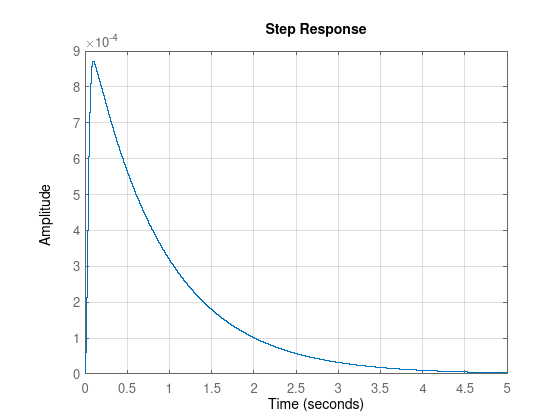

figure(2);clf; hold on;
step(Gz/(1+Gz*Cz)); grid on;